clc;
clear;
close all;

featuresHOG = cell(1,10);

for i = 1 :10
    featuresHOG{i} = sprintf('Features/HOG/%d/', i-1);
end

test_featuresHOG =cell(1,10);

for i = 1 :10
    test_featuresHOG{i} = sprintf('Test_Features/HOG/%d/', i-1);
end

listHogdb = cell(1,10);
nbHOGdb = cell(1,10);
for i = 1:10
    listHogdb{i} = dir([featuresHOG{i} '*.csv']);
    nbHOGdb{i} = numel(listHogdb{i});
end

listHogTest = cell(1,10);
nbHOGTest = cell(1,10);
for i = 1:10
    listHogTest{i} = dir([test_featuresHOG{i} '*.csv']);
    nbHOGTest{i} = numel(listHogTest{i});
end

maxnbHOGdb = max(cell2mat(nbHOGdb));
maxnbHOGTest = max(cell2mat(nbHOGTest));

test = readmatrix(sprintf("%s/%d.csv",featuresHOG{1},1));

hog_db = zeros(10,maxnbHOGdb, size(test,2));
for m = 1 : 10
    for n =1 :nbHOGdb{m}
         hog_db(m,n,:)= readmatrix(sprintf("%s/%d.csv",featuresHOG{m},n));
   end
end

hog_test = zeros(10,maxnbHOGTest, size(test,2));
for m = 1 : 10
    for n =1 :nbHOGTest{m}
         hog_test(m,n,:)= readmatrix(sprintf("%s/%d.csv",test_featuresHOG{m},n));
   end
end

labelData = zeros(10, maxnbHOGdb);
labelTest = zeros(10, maxnbHOGTest);
for k=1:10
    for l=1:nbHOGdb{k}
        labelData(k,l) = string(k-1);
    end
end

for k=1:10
    for l=1:nbHOGTest{k}
        labelTest(k,l) = string(k-1);
    end
end

labelData1 = reshape(labelData, size(labelData,1)*size(labelData,2),1);
labelTest1 = reshape(labelTest, size(labelTest,1)*size(labelTest,2),1);
trainingFeatures = reshape(hog_db, size(hog_db,1)*size(hog_db,2),size(hog_db,3)); 
testFeatures = reshape(hog_test, size(hog_test,1)*size(hog_test,2), size(hog_test,3));

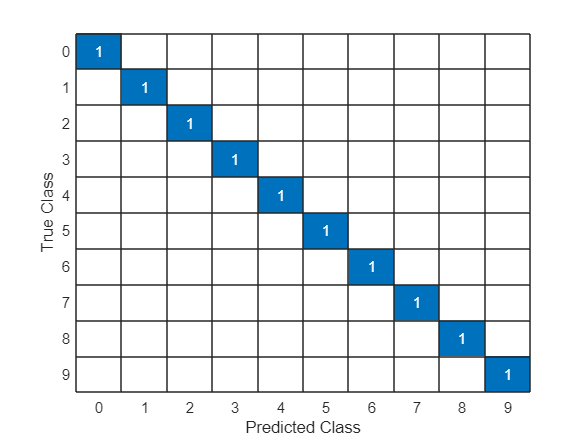

handle1 = @extractHOGFeatures;
imgGroup = sprintf('Test3/Group%d/', 1);
listimgTest = dir([imgGroup '*.jpeg'] );
nbimg = numel(listimgTest);
hog2 = zeros(max(nbimg),900);
labelTestGroup =zeros(max(nbimg),1);
for i =1:nbimg
challenge = rgb2gray(imread(sprintf("%s%d.jpeg",imgGroup,i-1))); 
[hog2(i,:), hogVisualization]= feval(handle1, challenge, 'NumBins', 9, 'CellSize', [16 16]);
labelTestGroup(i) = i-1;
end

classifier = fitcecoc(trainingFeatures,labelData1);
predictResults = predict(classifier,hog2);
cm  = confusionchart(labelTestGroup,predictResults);

% predictLabels = predict(classifier,testFeatures);

% confusionchart(labelTest1,predictLabels);